# **Solution:**

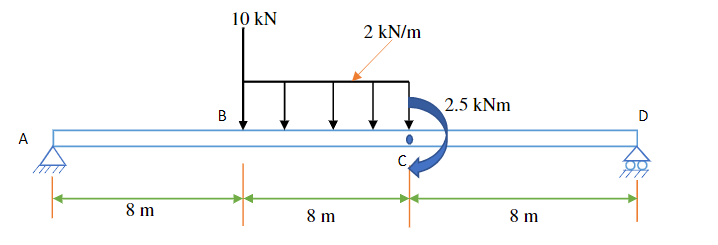

**Finding out Reaction Forces at A and D**

Since the beam is in equilibrium in y direction, the net force in y direction will be 0.

Σ Fy = 0                    

A + D – 10 – 16 = 0 

Now the moment of all forces about A is 0

Σ MA = 0 

(10*8) + (12*2*8) + 2.5 – (D * 24) = 0

syms a d
eqn1 = a + d - 10 - 16 == 0;
eqn2 = (10*8) + (12*2*8) + 2.5 - (d * 24) == 0; 
%%%% Solving the 2 equations to find reaction at a and d %%%%
sol = solve([eqn1, eqn2], [a , d]);

%%%% A and D are reaction forces at a and d respectively %%%%
A = sol.a

$$A = \frac{233}{16}$$

D = sol.d

$$D = \frac{183}{16}$$

**Shear Force diagram:-**

- When x is between A to B:- 

%%%% F1 is the shear force at a position x between A and B %%%%
syms x F
eqn = A - F == 0;
F1 = solve(eqn,F)

$$F1 = \frac{233}{16}$$

- When x is between B to C:- 

%%%% F2 is the shear force at a position x between B and C %%%%
syms x F
eqn = A - 10 - 2*(x - 8) - F == 0;
F2 = solve(eqn,F)

$$F2 = \frac{329}{16}-2\,x$$

- When x is between C to D:-

%%%% F3 is the shear force at a position x between C and D %%%%
syms x F
eqn = A - 10 - 2*8 - F == 0;
F3 = solve(eqn,F)

$$F3 = -\frac{183}{16}$$

Now plotting the shear force diagram

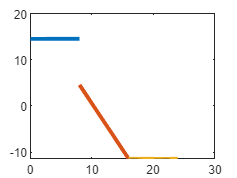

%%%% Plotting shear force diagram %%%%
t = linspace(0,8);
plot(t, subs(F1,t),'LineWidth',3);
hold on;
t = linspace(8,16);
plot(t, subs(F2,t),'LineWidth',3);
hold on;
t = linspace(16,24);
plot(t, subs(F3,t),'LineWidth',3)
hold off;

**Bending Moment diagram:-**

- When x is between A to B:-

%%%% M1 is the shear force at a position x between A and B %%%%
syms x M
eqn = M == A*x;
M1 = solve(eqn,M)

$$M1 = \frac{233\,x}{16}$$

- When x is between B to C:-

%%%% M2 is the shear force at a position x between B and C %%%%
syms x M
eqn = M == A*x - 10*(x - 8) - 2*(x - 8)*(x - 8)/2;
M2 = solve(eqn,M)

$$M2 = -x^{2}+\frac{329\,x}{16}+16$$

- When x is between C to D:-

%%%% M3 is the shear force at a position x between C and D %%%%
syms x M
eqn = M == A*x - 10*(x - 8) - 2*(8)*(x - 12) + 2.5;
M3 = solve(eqn,M)

$$M3 = \frac{549}{2}-\frac{183\,x}{16}$$

Now plotting the bending moment diagram

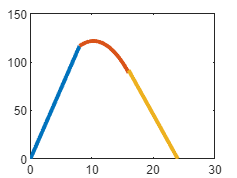

%%%% Plotting the bending moment diagram %%%%
t = linspace(0,8);
plot(t, subs(M1,t),'LineWidth',3);
hold on;
t = linspace(8,16);
plot(t, subs(M2,t),'LineWidth',3);
hold on;
t = linspace(16,24);
plot(t, subs(M3,t),'LineWidth',3)
hold off;